# Uniform sampling of E. coli core via Riemannian Hamiltonain Monte Carlo (RHMC)

## Author(s): Yunbum Kook (Georgia Tech), Yin Tat Lee (University of Washington), Ruoqi Shen (University of Washington), Santosh Vempala (Georgia Tech)

## Reviewer(s): 

## INTRODUCTION

The flux space $\Omega$ for a given set of biochemical and physiologic constraints is represented by: 


$$\Omega = \{v \mid Sv=b; l \leq v\leq u\}$$


where $v$ represents feasible flux vectors,  $S\in\mathcal{Z}^{m\times n}$ the stoichiometric matrix, while $l$ and $u$ are lower and upper bounds on fluxes. These criteria still allow a wide range of admissible flux distributions which, in FBA are commonly further restricted by introducing an objective to optimise, transforming the question of admissible fluxes into an FBA problem${\;}^1$ of the form


$$\begin{array}{ll}
\min\limits _{v} & c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $c$ is a linear biological objective function (biomass, ATP consumption, HEME production, etc.). Even under these conditions there is commonly a range of optimal flux distributions, which can be investigated using flux variability analysis. If the general capabilities of the model are of interest, however, uniform sampling of the entire flux space $\Omega$ is able to provide an unbiased characterization, and therefore, can be used to investigate the biochemical networks. It requires collecting a statistically meaningful number of flux distributions uniformly spread throughout the whole flux space and then analysing their properties. There are three basic steps to perform a uniform sampling for a set of feasible fluxes:

- Define the flux space to be sampled from physical and biochemical constraints

- Randomly sample the defined flux space based on uniform statistical criteria

- If is necessary, section the flux space according to post-sampling.

In this tutorial, we introduce how to run a new sampling scheme called the Riemannian Hamiltonian Monte Carlo (RHMC) for uniform or Gaussian sampling from the flux space. This algorithm first preprocesses the flux space and then performs uniform sampling based on the RHMC. Especially for large-size instances, you can find a significant speed-up in sampling compared to the default sampling algorithm, the coordinate hit-and-run with rounding (CHRR). First of all, the preprocessing part in the RHMC is numerically more stable and finishes in one minute even for an instance with 100000 reactions, whereas the preprocessing basd on John's ellipsoid in the CHRR takes super-linear time in dimensions of instances. Next, the sampling procedure iteself in the RHMC is substantially faster than the random walk based on the coordinate hit-and-run in the CHRR, since the random walk based on the RHMC extremely mixes well compared to the CHRR.

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

Please note that some of the plotting options in the tutorial require Matlab 2016a or higher. Moreover, the tutorial requires a working installation of the Parallel Computing Toolbox.

% uncomment this line below to see what toolboxes are installed
% ver

In this tutorial, we will perform FVA using the function `fluxVariability`. Change the variable `options.useFastFVA = 1` to use `fastFVA `instead`.` Note that the solver ibm_cplex is required for the function fastFVA.

options.useFastFVA = 0;

## PROCEDURE

## Load E. coli core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

## E. coli core in aerobic an anaerobic conditions

Remove the objective from the model and set a small lower bound on the rate of the biomass reaction

biomassRxnAbbr = 'Biomass_Ecoli_core_N(w/GAM)-Nmet2';
ibm = find(ismember(model.rxns, biomassRxnAbbr));  % column index of the biomass reaction
model.lb(ibm)=0.05;
model.c(:)=0;

We will investigate ATP energy production with limited and unlimited oxygen uptake. 

aerobicModel = changeRxnBounds(model,'EX_o2(e)',-17,'l');
anAerobicModel = changeRxnBounds(model,'EX_o2(e)',-1,'l');

## Sampling

The RHMC can be called via the function `sampleCbModel`. The main inputs to `sampleCbModel` are a COBRA model structure, the name of the selected sampler, and a parameter struct that controls properties of the sampler used. In the instance of the RHMC, the time limit for sampling (`maxTime)` and the number of samples (`nPointsReturned)` are the only parameters you need to set for uniform sampling, since other parameters for the RHMC are automatically set by the algorithm. You can also run a parallel version of the RHMC by setting `nWorkers` more than 1, which is set by 1 as a default. In case you want to sample from the Gaussian distribution with mean `vMean` and diagonal covariance matrix `vCov `(i.e., a probability density is proportional to $e^{-\frac{(x-\mu)^{T}\Sigma^{-1}(x-\mu)}{2}}$, where $\mu = vMean$ and $\Sigma = diag(vCov)$), you should provide these vectors as fields to the model struct.

Once you feed these parameters and run the RHMC, you obtain as many statistically independent samples as you requested. If the running time of the RHMC passes the time limit, then it will terminate and return independent samples drawn during the time limit. 

You can set additional parameters including nWorkers

options.nPointsReturned = 1000;
options.maxTime = 3600; % 1hr
%options.nWorkers = 1 % without parallelization (default case)

% Uniform Sampling
[~, X1_un] = sampleCbModel(aerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:15 | 00d:00:00:00 | ######################### |  1064 /  1000 | 0.953233 | 0.200000 |     26.1
Done!


[~, X1_lim] = sampleCbModel(anAerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:16 | 00d:00:00:00 | ######################### |  1206 /  1000 | 0.959644 | 0.181818 |     25.2
Done!


% Gaussian Sampling
% If you want to sample from the Standard Gaussian, you should provide the
% mean vector and the covariance vector used for a diagonal covariance
% matrix.

% Example for the standard Gaussian distribution
% numVar = size(aerobicModel.S, 2);
% aerobicModel.vMean = zeros(numVar, 1); 
% aerobicModel.vCov = ones(numVar, 1);

The sampler outputs the sampled flux distributions (X_un and X_lim). 

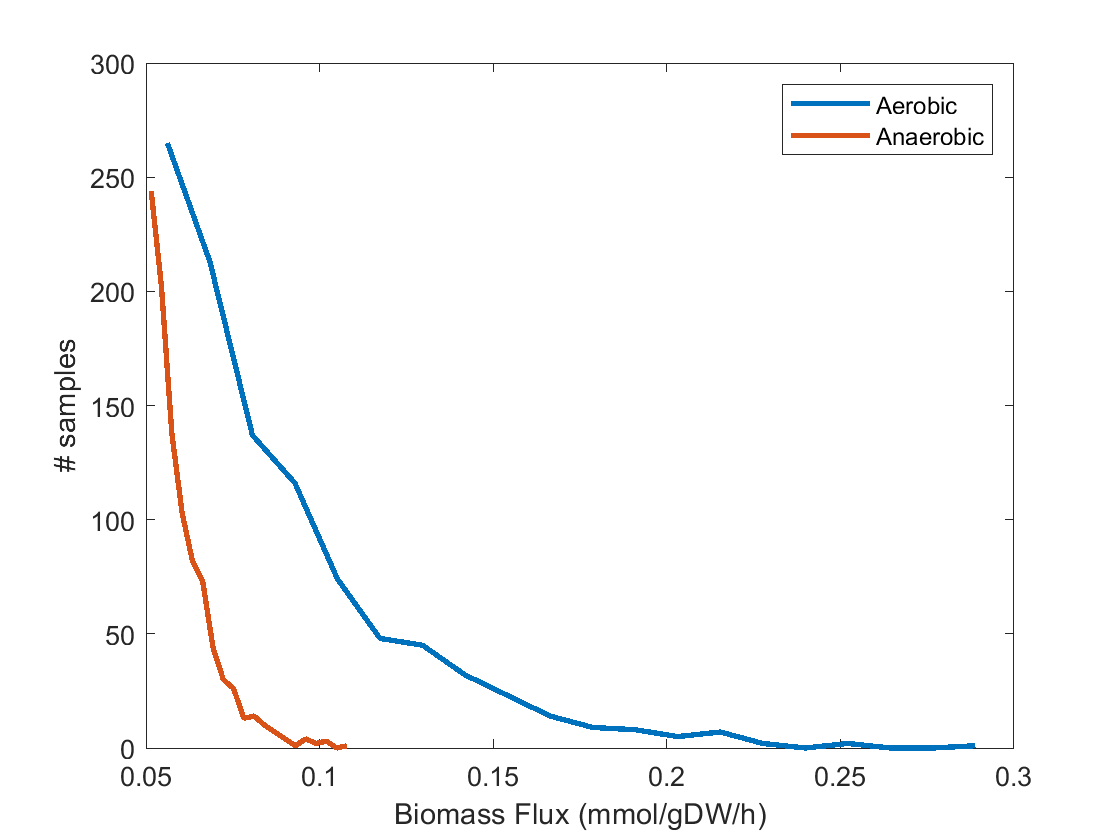

nbins = 20;
[yUn, xUn] = hist(X1_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X1_lim(ibm, :), nbins,'linewidth', 2);

figure;
plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

## Acknowledgements

Based on a ecoli core sampling tutorial by German A. Preciat Gonzalez and Ronan M.T. Fleming.

## References

1. Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol.* 28(3), 245-248 (2010).

2. Haraldsdóttir, H. S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based metabolic models. *Bioinformatics*. 33(11), 1741-1743 (2016).

3. Berbee, H. C. P., Boender, C. G. E., Rinnooy Ran, A. H. G., Scheffer, C. L., Smith, R. L., Telgen, J. Hit-and-run algorithms for the identification of nonredundant linear inequalities. *Math. Programming*, 37(2), 184-207 (1987).